Problem 1

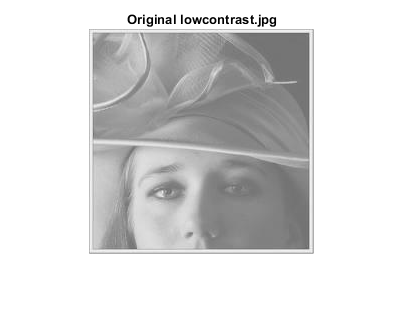

lowcontrast = imread("lowcontrast.jpg");
lowcontrastgray = im2gray(lowcontrast);

figure;
imshow(lowcontrastgray)
title('Original lowcontrast.jpg');

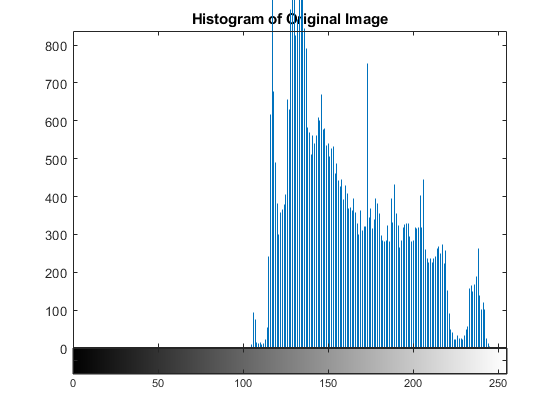


figure;
imhist(lowcontrastgray)
title('Histogram of Original Image')

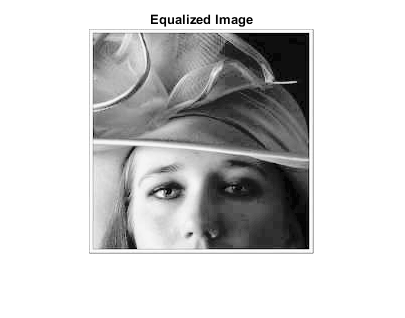


figure;
equalized = my_histeq(lowcontrastgray);
imshow(equalized)
title('Equalized Image')

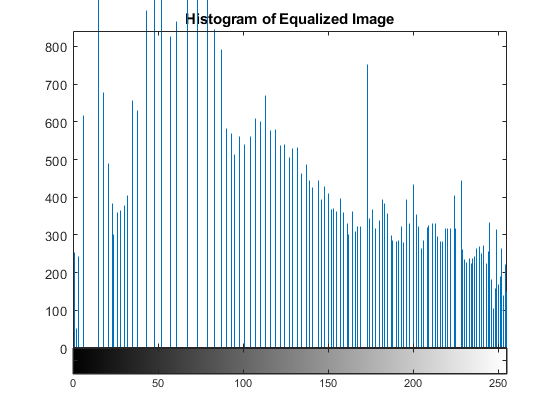


figure;
imhist(equalized)
title('Histogram of Equalized Image')

Problem 2

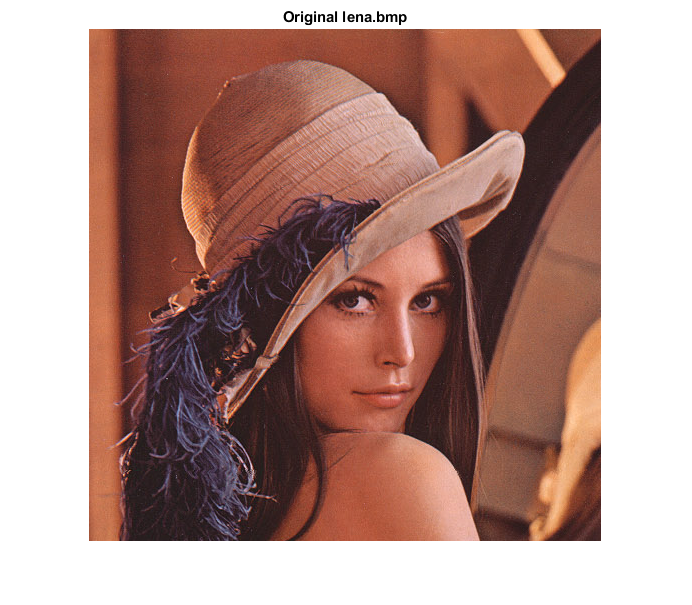

lena_rgb = imread('lena.bmp');
figure;
imshow(lena_rgb)
title('Original lena.bmp');

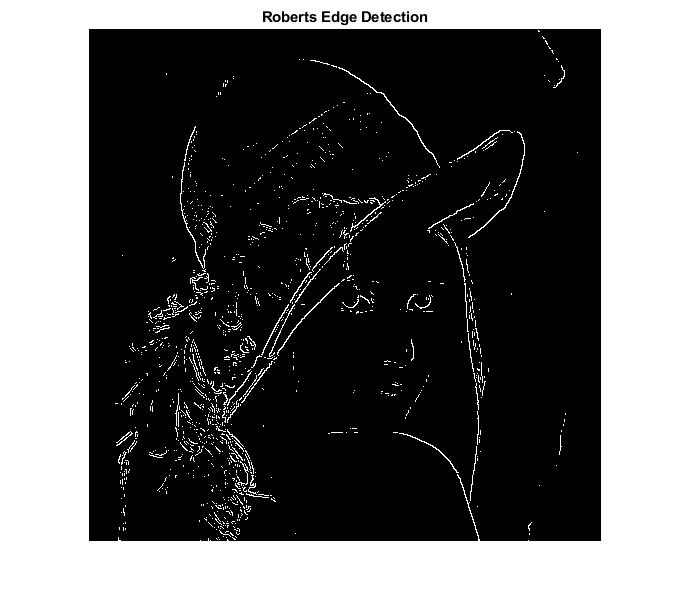


lena_gray = rgb2gray(lena_rgb);

a = edge(lena_gray, 'roberts');
figure;
imshow(a)
title('Roberts Edge Detection');

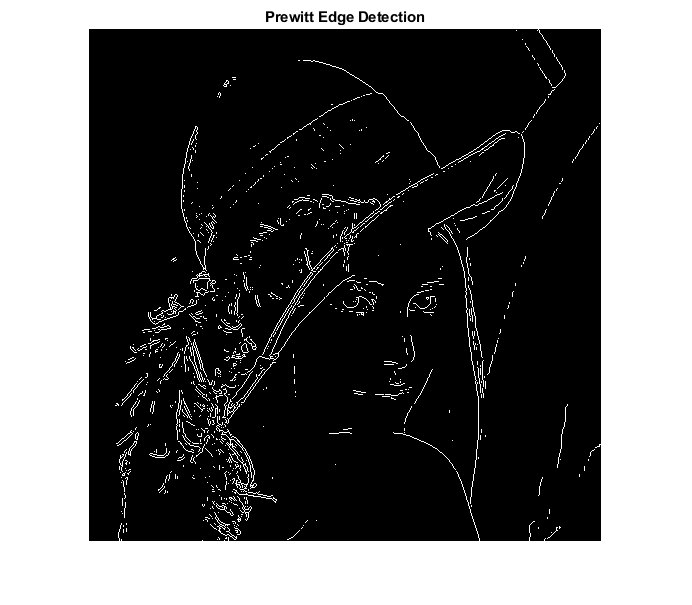


b = edge(lena_gray, 'prewitt');
figure;
imshow(b)
title('Prewitt Edge Detection');

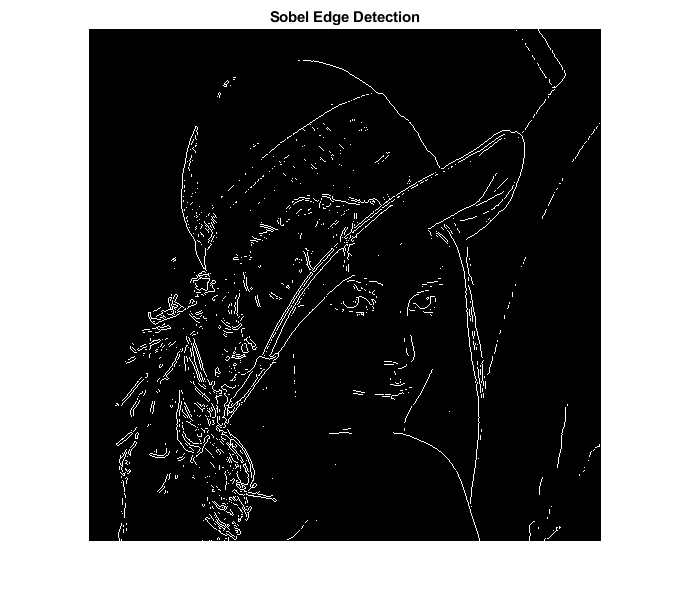


c = edge(lena_gray, 'sobel');
figure;
imshow(c)
title('Sobel Edge Detection');

Problem 3

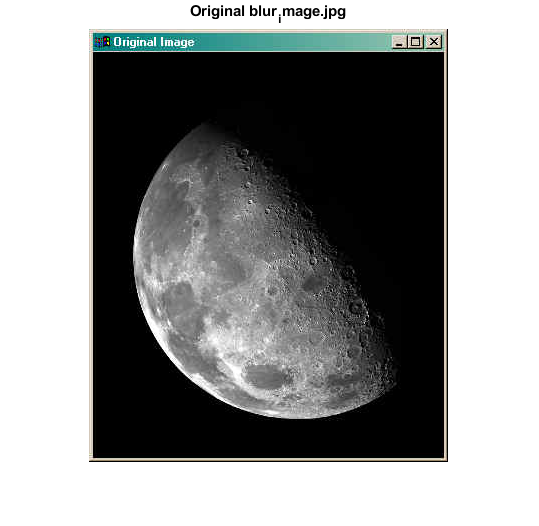

blur = imread('blur_image.jpg');

figure;
imshow(blur)
title('Original blur_image.jpg')

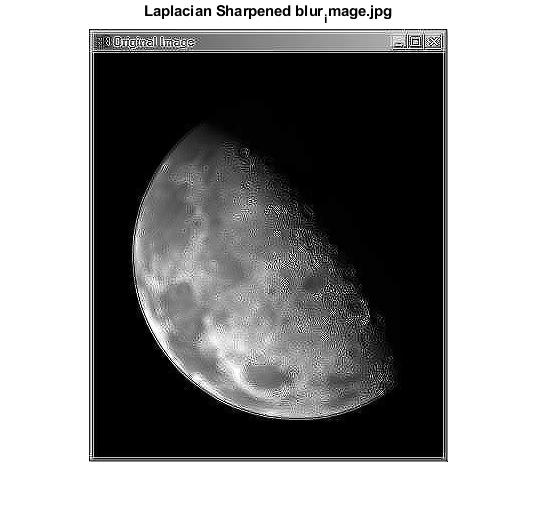


figure;
img = laplacian(blur);
imshow(img)
title('Laplacian Sharpened blur_image.jpg')

Functions

function eq = my_histeq(img)
    M = 255; % max intensity value
    counts = imhist(img); % get the original histogram
    pr = counts / numel(img); % PDF of original intensities
    cdf = cumsum(pr); % cdf = total probability
    mapping = M * cdf; % scale cdf by max intensity
    eq = uint8(mapping(double(img) + 1)); % apply mapping to each pixel
end

function blurred = laplacian(img)
    img = im2gray(img);
    img = double(img);
    
    L = [0, 1, 0;
         1, -4, 1;
         0, 1, 0; ];
    
    laplace = imfilter(img, L);
    blurred = img + laplace;
    blurred = uint8(blurred);
end